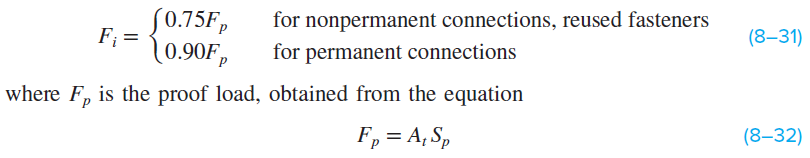

clear
format shortG
u = symunit;
S_y = 340 * u.MPa; %yield strength class 4.8
d = 4 * u.mm;
E = 207 * u.GPa;
A_t = 8.78 *u.mm^2; %tensile stress cross section area M4
A_r = 7.75 *u.mm^2; %areal fra roddiameter se table 8-1 i shigleys eller one note
A_d = pi/4 * d^2;   % Skaftareal [mm^2]
d_r = sqrt(4 * A_r / pi); % root diameteren
d_m = (d + d_r)/2; %middeldiameter
d_w = 7 * u.mm; % washer 
l = 0.7 * u.mm; %pitch
l_k =  29.9* u.mm; % = t + t = 2*t;    %Klemme længde (regnes kun til midt i underlagets nedre del) [mm]
L = 35* u.mm;% t + t + H;          % Boltlængde  [mm]
L_T = 35 * u.mm - 2.1* u.mm;          % Gevindlængde  [mm] %se også if statment nedenfor
l_d = L - L_T         % Skaft længde  [mm]

$$l\_d = \frac{21}{10}\,\mathrm{mm}$$

l_t = l_k - l_d         % Gevindlængde i indgreb  [mm]

$$l\_t = \frac{139}{5}\,\mathrm{mm}$$

f = 0.15; %friktionskoefficienten i gevind
fc = 0.10; %friktionskoefficienten i spændeskive
alpha = 30; %grader %30 grader er den typiske vinkel
d_c_min = 4.3 * u.mm; %mindste diameter på spændeskive
d_c_max = 8 * u.mm; %største diameter på spændeskive
d_c =  (d_c_min + d_c_max) / 2;%middel diameter på spændeskive

S_p = 0.85 * S_y; % proff strength
F_p = S_p * A_t; % proff force
F_i = 0.90 * F_p; % n_bolts% nonperm
F_i_ = vpa(unitConvert(F_i, u.N), 5)

$$F\_i\_ = 2283.7\,N$$

F_spring = [115.05 31.35 31.35] * u.N;
P = F_spring

$$P = \left(\begin{array}{ccc} \frac{2301}{20}\,N & \frac{627}{20}\,N & \frac{627}{20}\,N \end{array}\right)$$


tau_max = S_y;
T_max_calc = tau_max / 16 * (pi * d_r.^3); % torque at max torsion
T_max_calc_ = vpa(unitConvert(T_max_calc, u.N*u.m), 5)

$$T\_max\_calc\_ = 2.0693\,N\,m$$


lambda = atan(l/(pi*d_m)); %stigningsvinklen i gevind

T_for = (F_i * d_m/2) * ((tan(lambda) + f * secd(alpha)) /...
    (1 - f * tan(lambda) * secd(alpha))) + (F_i * fc * d_c)/2;
T_for_ = vpa(unitConvert(T_for, u.N*u.m), 5)

$$T\_for\_ = 1.6733\,N\,m$$


% I det tilfælde af at de to 𝑓 og 𝑓𝑐 = 0,15 ender det med at 𝐾 = 0.2
T_simpel = 0.2 * F_i * d; %den reducered formel når d_c = 1.25 * d

T_simpel_ = vpa(unitConvert(T_simpel, u.N * u.m), 4)

$$T\_simpel\_ = 1.827\,N\,m$$

Bolts and material stiffness

k_b = (A_d * A_t * E) / (A_d * l_t + A_t * l_d);
k_b = vpa(unitConvert((A_d * A_t * E) / (A_d * l_t + A_t * l_d), u.MN), 5) % ligning 8-17

$$k\_b = 62.099\,\frac{\mathrm{MN}}{m}$$



% Stivhed for matrialet
k_m = (pi * E * d * tand(alpha)) /...
    (2 * log(((l_k * tand(alpha) + d_w - d) * (d_w + d)) / ...
    ((l_k * tand(alpha) + d_w + d) * (d_w - d)) ) ); %ligning 8 -21

k_m = vpa(unitConvert(k_m, u.MN), 5)

$$k\_m = 776.92\,\frac{\mathrm{MN}}{m}$$


%Samling stivhedskontanten
C = k_b / (k_b + k_m)

$$C = 0.074013374437445909526106036491031$$


% Spændinger i bolten kan beregnes som
% sigma_b = F_b/A_t

P_b = vpa(unitConvert(C * P, u.N), 3)

$$P\_b = \left(\begin{array}{ccc} 8.52\,N & 2.32\,N & 2.32\,N \end{array}\right)$$

sigma_b = vpa(unitConvert((F_i_ + P_b) / A_t, u.MPa), 3)

$$sigma\_b = \left(\begin{array}{ccc} 261.0\,\mathrm{MPa} & 260.0\,\mathrm{MPa} & 260.0\,\mathrm{MPa} \end{array}\right)$$



% Sikkerhed imod flydning

n_p = vpa(unitConvert(S_p ./ sigma_b, 'SI'), 3) % ligning 8-28

$$n\_p = \left(\begin{array}{ccc} 1.11 & 1.11 & 1.11 \end{array}\right)$$

n_p = vpa(unitConvert(S_p * A_t ./ (C*P + F_i), 'SI'), 3)  % ligning 8-28

$$n\_p = \left(\begin{array}{ccc} 1.11 & 1.11 & 1.11 \end{array}\right)$$

**Springs**

1 kNm

clear
clf

L0 = 57.15e-3; % free length
L_extended = 111e-3;
L_retracted = 77e-3;
L_full = 124e-3

L_full =         0.124


k_axial = 0.57e3; % N/mm --> N/m % max kraft 41,87, max vandring 66,80, total lenth 123,95 L0 = 57,15
% E08500632250S % varenummer trækfjeder SODEMANN
x_axial = (L_extended - L0) % 55e-3; % udspændt fjeder til træk af claw

x_axial =       0.05385




x_spring_pre = (L_retracted - L0)

x_spring_pre =       0.01985


%down to 77 from 110 (44)
F_axial_pre = k_axial * x_spring_pre

F_axial_pre =        11.314


F_axial = k_axial * x_axial

F_axial =        30.695


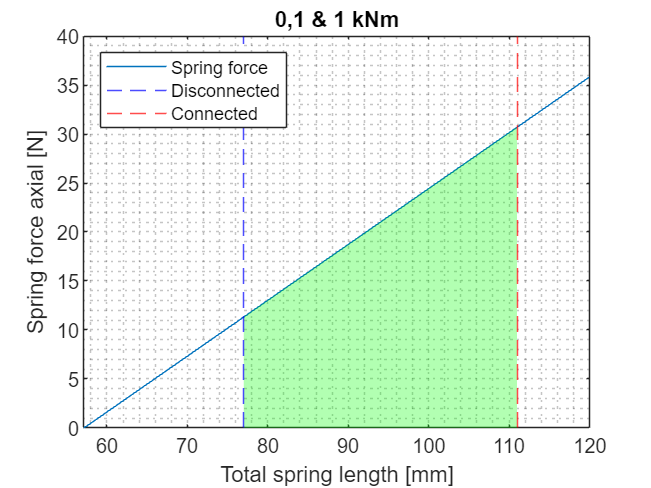


X = linspace(L0,L_full,100);
F_axial_plot = k_axial * (X-L0);
plot(X*1e3, F_axial_plot, DisplayName="Spring force")
hold on

fill_X = [linspace(L_retracted, L_extended, 100), L_extended, L_retracted]; % Extend to close area
fill_Y = [k_axial * (linspace(L_retracted, L_extended, 100) - L0), 0, 0]; % Add zeros for base
fill(fill_X * 1e3, fill_Y, 'g', 'FaceAlpha', 0.3, ...
    EdgeColor='none',HandleVisibility='off') % Fill with green color



xline(L_retracted*1e3, 'b--', DisplayName="Disconnected")
xline(L_extended*1e3, 'r--', DisplayName="Connected")
% xline(L0*1e3, 'g--', DisplayName="l_0")

xlabel("Total spring length [mm]")
ylabel("Spring force axial [N]")
xlim([L0*1e3, 120])
legend('Location', 'northwest')
title("0,1 & 1 kNm")
grid('minor')
hold off

10 kNM

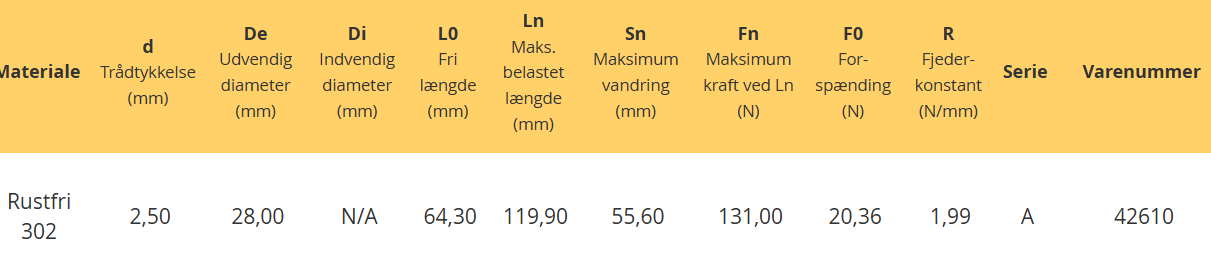

L0 = 64.30e-3

L0 =        0.0643


L_full = 119.9e-3

L_full =        0.1199


k_axial = 1.99e3; % N/mm --> N/m % max kraft 131,00, max vandring 55.60
% serie A  % varenummer 42610 trækfjeder SODEMANN rustfri

L_extended = 117e-3;
L_retracted = 72e-3;
x_axial = L_extended - L0

x_axial =        0.0527


x_spring_pre = (L_retracted - L0)

x_spring_pre =        0.0077


%down to 77 from 110 (44)
F_axial_pre = k_axial * x_spring_pre

F_axial_pre =        15.323


F_axial = k_axial * x_axial

F_axial =        104.87


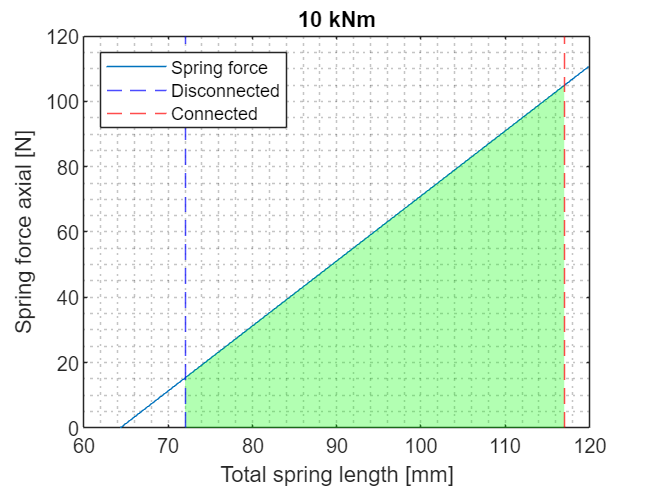


X = linspace(L0,L_full,100);
F_axial_plot = k_axial * (X-L0);
plot(X*1e3, F_axial_plot, DisplayName="Spring force")
hold on

fill_X = [linspace(L_retracted, L_extended, 100), L_extended, L_retracted]; % Extend to close area
fill_Y = [k_axial * (linspace(L_retracted, L_extended, 100) - L0), 0, 0]; % Add zeros for base
fill(fill_X * 1e3, fill_Y, 'g', 'FaceAlpha', 0.3, ...
    EdgeColor='none',HandleVisibility='off') % Fill with green color



xline(L_retracted*1e3, 'b--', DisplayName="Disconnected")
xline(L_extended*1e3, 'r--', DisplayName="Connected")
% xline(L0*1e3, 'g--', DisplayName="l_0")

xlabel("Total spring length [mm]")
ylabel("Spring force axial [N]")
legend('Location', 'northwest')
title("10 kNm")
grid('minor')
hold off

Weight to drag

g = 9.82; %
m = [4.7 1.9];
F_W = m * g;
f_s = 0.25;
F_fric = F_W * f_s

F_fric =        11.539       4.6645
